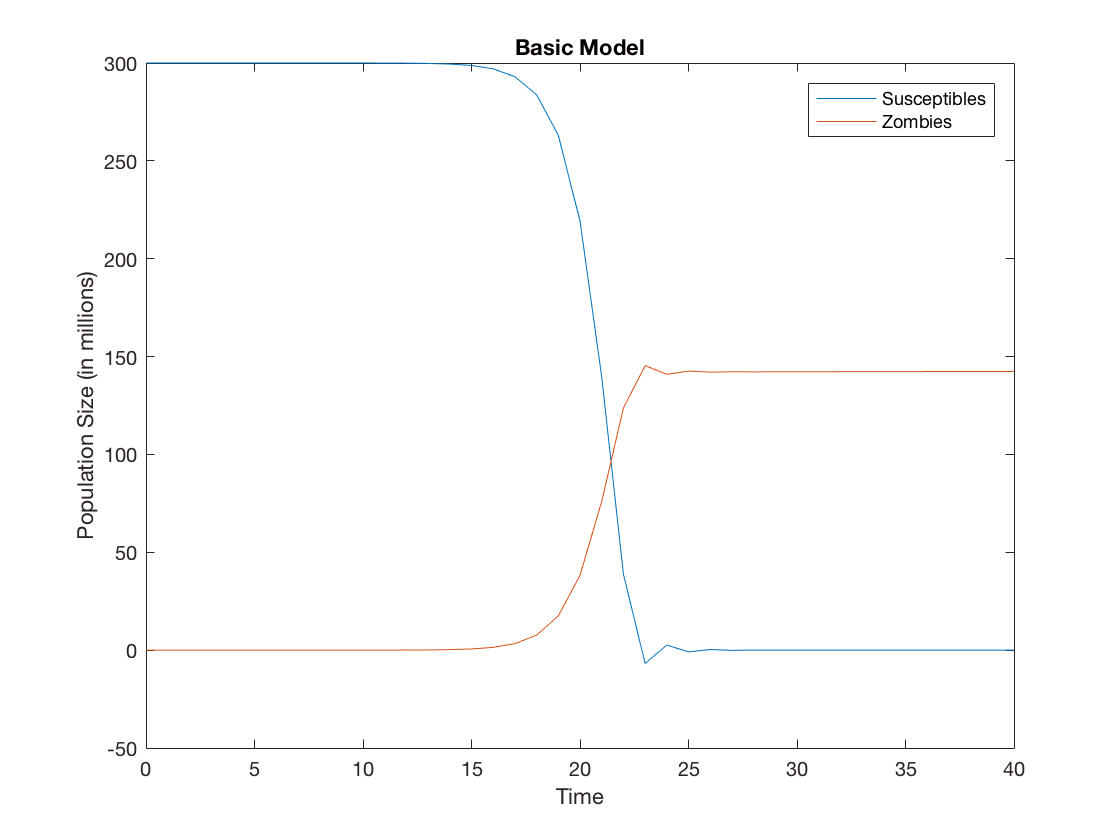

%Part 1 - Basic Model with outbreak
close all; clear all; format longG;
%defining variables
a = 0.005;
b = 0.0095;
z = 0.0001;
pie = 0.03;
d = 0.0001;
t0 = 0; tF = 40; dt = 1; t = t0:dt:tF;
S = 0*t; Z = 0*t; R = 0*t;
S(1) = 300; Z(1) = 0; R(1) = 0;

for n = 1:length(t)-1
    S(n+1) = S(n) + dt*(-S(n)*(b*Z(n))); %setting background birth rate & death rate to 0
    Z(n+1) = Z(n) + dt*(z*R(n) + Z(n)*S(n)*(b - a));
    R(n+1) = R(n) + dt*(S(n)*(d + a*Z(n)) - z*R(n));
end
plot(t, S, t, Z)
legend('Susceptibles','Zombies')

title('Basic Model')
xlabel('Time')
ylabel('Population Size (in millions)')